# Estudio reproducible: dinámica y control de un cuadricóptero 6-DoF

Plataforma: MATLAB base (sin toolboxes externos). Convención: marco inercial NED; z positivo hacia abajo. Estado: X = [r_I(3); v_I(3); q_B2I(4, escalar primero); omega_B(3)].

IMPORTANTE: - Los parámetros físicos marcados como supuestos no son datos experimentales. - El modelo usa empuje instantáneo de rotores; no modela la dinámica eléctrica. - La replanificación es geométrica y reactiva, no un planificador global. - Este archivo es un script .m compatible con MATLAB. Para obtener .mlx: abra el archivo en MATLAB Editor > Save As > MATLAB Live Code (*.mlx). También puede ejecutar: matlab.internal.liveeditor.openAndConvert('cuadricoptero_6DoF_estudio.m','cuadricoptero_6DoF_estudio.mlx') en versiones que dispongan de esa función interna. La conversión debe verificarse.

Salidas creadas en ./resultados_cuadricoptero: MAT de datos, CSV de métricas/tablas y PNG de figuras.

clear; clc; close all;
rng(7,'twister');
salidaDir = fullfile(pwd,'resultados_cuadricoptero');
if ~exist(salidaDir,'dir'), mkdir(salidaDir); end

## 1. Parámetros, límites y configuración numérica

p = configurarParametros();
cfg = struct;
cfg.dt = 0.005;             % s, paso RK4 nominal
cfg.dtFino = 0.0025;        % s, prueba de sensibilidad
cfg.metodo = 'RK4';         % 'Euler', 'RK4' o 'RKF45'
cfg.AbsTol = 1e-9;
cfg.RelTol = 1e-7;
cfg.hInicial = 0.01;
cfg.hMin = 1e-7;
cfg.hMax = 0.05;
cfg.seguridad = 0.9;
cfg.maxTiempo = 30;         % s, protección frente a ejecuciones anómalas

% Puntos NED [m]. z<0 significa ascenso.
P = [0 0 0; 2 0 -1; 4 2 -2; 6 2 -1; 8 0 0];
T0 = 12;                    % s, duración total nominal
yaw0 = 0;                   % rad
tDet = 5.0;                 % s, instante de detección del obstáculo
obst.centro = [4.0; 0.75; -1.0]; % m, esfera imprevista
obst.radio = 0.65;                % m
obst.margen = 0.25;               % m, radio de seguridad adicional

## 2. Validación previa del modelo y los actuadores

validacion = validarModelo(p);
disp('--- Validación previa ---');

--- Validación previa ---


disp(struct2table(validacion,'AsArray',true));

    errorEquilibrioN    errorAsignacionN    errorRotacion    normaCuaternion    empujeMaxRotor_N    empujeMaxAgregado_N    rotorHover_rad_s    hoverDentroLimites
    ________________    ________________    _____________    _______________    ________________    ___________________    ________________    __________________

           0                   0                  0                 1                 8.1                  32.4                 495.23               true        



assert(validacion.errorEquilibrioN < 1e-8, 'Falló equilibrio de fuerzas.');
assert(validacion.errorAsignacionN < 1e-8, 'Falló asignación simétrica.');
assert(validacion.errorRotacion < 1e-10, 'Falló matriz de rotación.');

## 3. Experimento 1: caso base (minimum snap + RK4)

refBase = generarMinimumSnap(P,T0);
base = simularEscenario(p,cfg,refBase,struct('tipo','nulo'),[],[],yaw0);
metBase = calcularMetricas(base,p,[],[]);
disp('--- Métricas del caso base ---');

--- Métricas del caso base ---


disp(struct2table(metBase,'AsArray',true));

    RMSE_m    errorMax_m    J_empuje_N2s    J_momentos_N2m2s    empujeMax_N    momentoMax_Nm    saturacion_pct    inclinacionMax_deg    omegaCuerpoMax_rad_s    tiempoVuelo_s    distanciaMinima_m    colision
    ______    __________    ____________    ________________    ___________    _____________    ______________    __________________    ____________________    _____________    _________________    ________

    0.0329     0.059865        1162.7          6.6796e-06         10.268         0.0021228            0                 7.9797                 0.148                 12          

save(fullfile(salidaDir,'caso_base.mat'),'base','refBase','p','cfg','P','T0','metBase');

## 4. Sensibilidad numérica: RK4 con dos pasos temporales

cfgA = cfg; cfgA.dt = cfg.dt;
cfgB = cfg; cfgB.dt = cfg.dtFino;
solA = simularEscenario(p,cfgA,refBase,struct('tipo','nulo'),[],[],yaw0);
solB = simularEscenario(p,cfgB,refBase,struct('tipo','nulo'),[],[],yaw0);
conv = struct;
conv.dt_grueso_s = cfgA.dt;
conv.dt_fino_s = cfgB.dt;
conv.diferencia_RMSE_m = abs(calcularMetricas(solA,p,[],[]).RMSE_m - ...
                             calcularMetricas(solB,p,[],[]).RMSE_m);
conv.max_diferencia_posicion_m = compararSoluciones(solA,solB);
conv.max_error_norma_cuaternion = max(abs(vecnorm(solB.X(:,7:10),2,2)-1));
disp('--- Sensibilidad numérica RK4 ---');

--- Sensibilidad numérica RK4 ---


disp(struct2table(conv,'AsArray',true));

    dt_grueso_s    dt_fino_s    diferencia_RMSE_m    max_diferencia_posicion_m    max_error_norma_cuaternion
    ___________    _________    _________________    _________________________    __________________________

       0.005        0.0025         5.6212e-06               4.2365e-06                    1.1102e-16        



writetable(struct2table(conv,'AsArray',true),fullfile(salidaDir,'sensibilidad_numerica.csv'));

## 5. Experimento 2: robustez (una variable por comparación)

escenarios = struct('nombre',{},'tipo',{},'factor',{},'viento',{});
for f = [0.8 1.0 1.2]
    escenarios(end+1) = struct('nombre',sprintf('duracion_%0.1f',f), ...
        'tipo','duracion','factor',f,'viento',struct('tipo','nulo')); %#ok<SAGROW>
end
for f = [0.8 1.0 1.2]
    escenarios(end+1) = struct('nombre',sprintf('masa_%0.1f',f), ...
        'tipo','masa','factor',f,'viento',struct('tipo','nulo')); %#ok<SAGROW>
end
vientos = {struct('tipo','nulo'), ...
           struct('tipo','constante','vector',[2.0;0.5;0]), ...
           struct('tipo','variable','amplitud',[1.5;0.8;0.25],'frecuencia',[0.45;0.7;0.3])};
nombresViento = {'viento_nulo','viento_constante','viento_variable'};
for k=1:numel(vientos)
    escenarios(end+1) = struct('nombre',nombresViento{k}, ...
        'tipo','viento','factor',1.0,'viento',vientos{k}); %#ok<SAGROW>
end

resultadosRobustez = struct('nombre',{},'tipo',{},'factor',{},'RMSE_m',{}, ...
    'errorMax_m',{},'J_empuje_N2s',{},'J_momentos_N2m2s',{}, ...
    'empujeMax_N',{},'momentoMax_Nm',{},'saturacion_pct',{}, ...
    'inclinacionMax_deg',{},'viable',{},'motivo',{});
for k=1:numel(escenarios)
    e = escenarios(k);
    pk = p; Tk = T0; vk = e.viento;
    if strcmp(e.tipo,'duracion'), Tk = T0*e.factor; end
    if strcmp(e.tipo,'masa'), pk.masa = p.masa*e.factor; end
    rk = generarMinimumSnap(P,Tk);
    sk = simularEscenario(pk,cfg,rk,vk,[],[],yaw0);
    mk = calcularMetricas(sk,pk,[],[]);
    viable = mk.saturacion_pct < 5 && mk.inclinacionMax_deg < p.inclinacionMax*180/pi ...
             && all(isfinite(sk.X(:)));
    motivo = "dentro de los límites monitorizados";
    if ~viable, motivo = "revisar saturación, inclinación o valores no finitos"; end
    resultadosRobustez(end+1) = struct('nombre',e.nombre,'tipo',e.tipo, ...
        'factor',e.factor,'RMSE_m',mk.RMSE_m,'errorMax_m',mk.errorMax_m, ...
        'J_empuje_N2s',mk.J_empuje_N2s,'J_momentos_N2m2s',mk.J_momentos_N2m2s, ...
        'empujeMax_N',mk.empujeMax_N,'momentoMax_Nm',mk.momentoMax_Nm, ...
        'saturacion_pct',mk.saturacion_pct,'inclinacionMax_deg',mk.inclinacionMax_deg, ...
        'viable',viable,'motivo',motivo); %#ok<SAGROW>
    if k==1, robustezEjemplo = sk; end %#ok<NASGU>
end
tablaRobustez = struct2table(resultadosRobustez);
disp('--- Tabla de robustez ---'); disp(tablaRobustez);

--- Tabla de robustez ---
           nombre               tipo        factor     RMSE_m     errorMax_m    J_empuje_N2s    J_momentos_N2m2s    empujeMax_N    momentoMax_Nm    saturacion_pct    inclinacionMax_deg    viable                   motivo                
    ____________________    ____________    ______    ________    __________    ____________    ________________    ___________    _____________    ______________    __________________    ______    _____________________________________

    {'duracion_0.8'    }    {'duracion'}     0.8      0.064

writetable(tablaRobustez,fullfile(salidaDir,'tabla_robustez.csv'));
save(fullfile(salidaDir,'robustez.mat'),'resultadosRobustez','tablaRobustez');

## 6. Experimento 3: obstáculo imprevisto y replanificación en línea

La primera trayectoria se genera sin conocer el obstáculo. En tDet se conserva el estado alcanzado y se sustituye solo la referencia futura.

replan = simularConReplanificacion(p,cfg,refBase,struct('tipo','nulo'), ...
                                   obst,tDet,yaw0);
metReplan = calcularMetricas(replan,p,obst,tDet);
tablaReplan = struct2table(metReplan,'AsArray',true);
tablaReplan.colision = replan.colision;
tablaReplan.distanciaMinima_m = replan.distanciaMinima;
tablaReplan.continuidadPosicion_m = replan.continuidadPosicion;
tablaReplan.continuidadVelocidad_mps = replan.continuidadVelocidad;
tablaReplan.continuidadAceleracion_mps2 = replan.continuidadAceleracion;
tablaReplan.duracion_s = replan.t(end)-replan.t(1);
tablaReplan.viable = ~replan.colision && replan.distanciaMinima > obst.radio && ...
    metReplan.saturacion_pct < 5 && metReplan.inclinacionMax_deg < p.inclinacionMax*180/pi;
disp('--- Viabilidad de replanificación ---'); disp(tablaReplan);

--- Viabilidad de replanificación ---
     RMSE_m     errorMax_m    J_empuje_N2s    J_momentos_N2m2s    empujeMax_N    momentoMax_Nm    saturacion_pct    inclinacionMax_deg    omegaCuerpoMax_rad_s    tiempoVuelo_s    distanciaMinima_m    colision    tDet_s    continuidadPosicion_m    continuidadVelocidad_mps    continuidadAceleracion_mps2    duracion_s    viable
    ________    __________    ____________    ________________    ___________    _____________    ______________    __________________    ____________________    ______

writetable(tablaReplan,fullfile(salidaDir,'tabla_replanificacion.csv'));
save(fullfile(salidaDir,'replanificacion.mat'),'replan','metReplan','obst','tDet');

## 7. Figura 1: diagrama de bloques

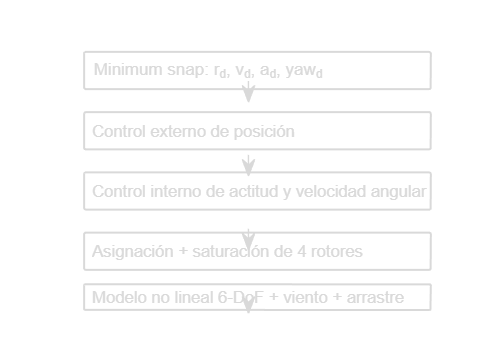

fig = figure('Color','w','Name','Arquitectura de control');
axis off; xlim([0 1]); ylim([0 1]);
bloques = { ...
    [0.05 0.78 0.9 0.13],'Minimum snap: r_d, v_d, a_d, yaw_d'; ...
    [0.05 0.57 0.9 0.13],'Control externo de posición'; ...
    [0.05 0.36 0.9 0.13],'Control interno de actitud y velocidad angular'; ...
    [0.05 0.15 0.9 0.13],'Asignación + saturación de 4 rotores'; ...
    [0.05 0.01 0.9 0.09],'Modelo no lineal 6-DoF + viento + arrastre'};
for i=1:size(bloques,1)
    rectangle('Position',bloques{i,1},'Curvature',0.08,'LineWidth',1.2);
    text(bloques{i,1}(1)+0.02,bloques{i,1}(2)+bloques{i,1}(4)/2, ...
        bloques{i,2},'FontSize',10,'VerticalAlignment','middle');
    if i<size(bloques,1)
        annotation('arrow',[0.5 0.5],[bloques{i,1}(2)-0.01 bloques{i+1,1}(2)+bloques{i+1,1}(4)+0.01]);
    end
end
exportarFigura(fig,salidaDir,'fig01_diagrama_bloques');

## 8. Figura 2: trayectoria 3D base

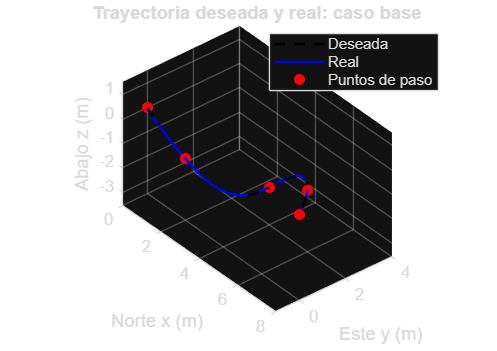

fig = figure('Color','w'); hold on; grid on; axis equal;
plot3(base.ref(:,1),base.ref(:,2),base.ref(:,3),'k--','LineWidth',1.5);
plot3(base.X(:,1),base.X(:,2),base.X(:,3),'b','LineWidth',1.4);
plot3(P(:,1),P(:,2),P(:,3),'ro','MarkerFaceColor','r');
xlabel('Norte x (m)'); ylabel('Este y (m)'); zlabel('Abajo z (m)');
title('Trayectoria deseada y real: caso base'); legend('Deseada','Real','Puntos de paso','Location','best');
view(40,25); exportarFigura(fig,salidaDir,'fig02_trayectoria_3D');

## 9. Figura 3: posición deseada y real

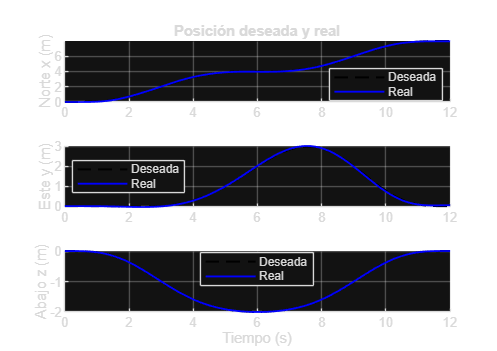

fig = figure('Color','w');
nombresEje = {'Norte x (m)','Este y (m)','Abajo z (m)'};
for j=1:3
    subplot(3,1,j); hold on; grid on;
    plot(base.t,base.ref(:,j),'k--','LineWidth',1.2);
    plot(base.t,base.X(:,j),'b','LineWidth',1.1);
    ylabel(nombresEje{j});
    if j==1, title('Posición deseada y real'); end
    if j==3, xlabel('Tiempo (s)'); end
    legend('Deseada','Real','Location','best');
end
exportarFigura(fig,salidaDir,'fig03_posicion_tiempo');

## 10. Figura 4: empuje y momentos reales

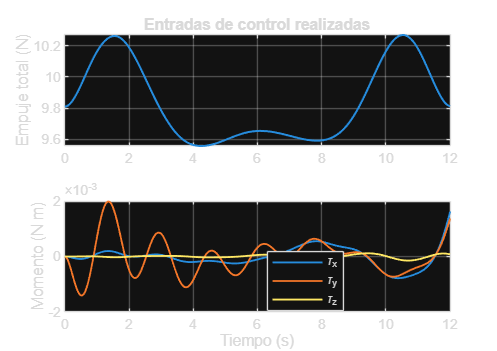

fig = figure('Color','w');
subplot(2,1,1); plot(base.t,base.Treal,'LineWidth',1.2); grid on;
ylabel('Empuje total (N)'); title('Entradas de control realizadas');
subplot(2,1,2); plot(base.t,base.tauReal,'LineWidth',1.1); grid on;
xlabel('Tiempo (s)'); ylabel('Momento (N m)');
legend('\tau_x','\tau_y','\tau_z','Location','best');
exportarFigura(fig,salidaDir,'fig04_control');

## 11. Figura 5: error por escenario de robustez

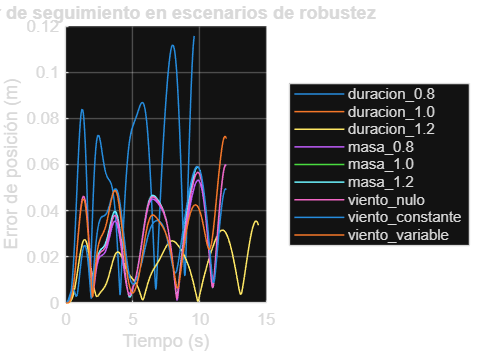

fig = figure('Color','w'); hold on; grid on;
% Se vuelven a ejecutar los nueve casos para obtener series temporales
% alineadas en tiempo. Se agrupan por el tipo de variación.
colores = lines(9); leyendas = {};
for k=1:numel(escenarios)
    e=escenarios(k); pk=p; Tk=T0; vk=e.viento;
    if strcmp(e.tipo,'duracion'), Tk=T0*e.factor; end
    if strcmp(e.tipo,'masa'), pk.masa=p.masa*e.factor; end
    ss=simularEscenario(pk,cfg,generarMinimumSnap(P,Tk),vk,[],[],yaw0);
    plot(ss.t,ss.errorPos,'Color',colores(k,:),'LineWidth',0.9);
    leyendas{end+1}=e.nombre; %#ok<SAGROW>
end
xlabel('Tiempo (s)'); ylabel('Error de posición (m)');
title('Error de seguimiento en escenarios de robustez');
legend(leyendas,'Interpreter','none','Location','eastoutside');
exportarFigura(fig,salidaDir,'fig05_errores_robustez');

## 12. Figura 6: trayectoria original/replanificada y obstáculo

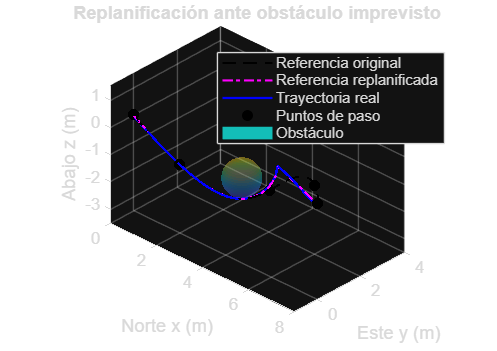

fig = figure('Color','w'); hold on; grid on; axis equal;
plot3(replan.refOriginal(:,1),replan.refOriginal(:,2),replan.refOriginal(:,3), ...
    'k--','LineWidth',1.2);
plot3(replan.ref(:,1),replan.ref(:,2),replan.ref(:,3),'m-.','LineWidth',1.3);
plot3(replan.X(:,1),replan.X(:,2),replan.X(:,3),'b','LineWidth',1.4);
plot3(P(:,1),P(:,2),P(:,3),'ko','MarkerFaceColor','k');
[xs,ys,zs]=sphere(24);
surf(obst.centro(1)+obst.radio*xs,obst.centro(2)+obst.radio*ys, ...
     obst.centro(3)+obst.radio*zs,'FaceAlpha',0.25,'EdgeColor','none');
xlabel('Norte x (m)'); ylabel('Este y (m)'); zlabel('Abajo z (m)');
title('Replanificación ante obstáculo imprevisto');
legend('Referencia original','Referencia replanificada','Trayectoria real', ...
       'Puntos de paso','Obstáculo','Location','best');
view(40,25); exportarFigura(fig,salidaDir,'fig06_replanificacion_3D');

## 13. Figura 7: error de replanificación

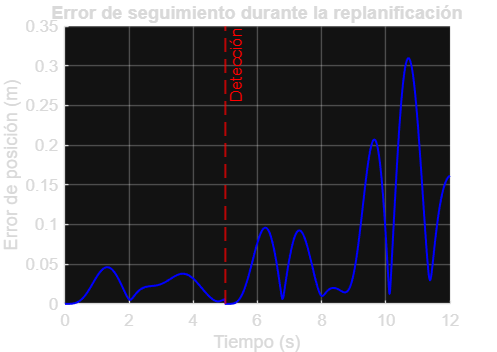

fig = figure('Color','w'); hold on; grid on;
plot(replan.t,replan.errorPos,'b','LineWidth',1.2);
xline(tDet,'r--','Detección','LineWidth',1.2);
xlabel('Tiempo (s)'); ylabel('Error de posición (m)');
title('Error de seguimiento durante la replanificación');
exportarFigura(fig,salidaDir,'fig07_error_replanificacion');

## 14. Exportación final y resumen verificable

baseTable = table(base.t,base.X(:,1),base.X(:,2),base.X(:,3), ...
    base.ref(:,1),base.ref(:,2),base.ref(:,3),base.errorPos,base.Treal, ...
    base.tauReal(:,1),base.tauReal(:,2),base.tauReal(:,3), ...
    'VariableNames',{'t_s','x_m','y_m','z_m','xd_m','yd_m','zd_m', ...
    'error_m','T_N','tau_x_Nm','tau_y_Nm','tau_z_Nm'});
writetable(baseTable,fullfile(salidaDir,'datos_caso_base.csv'));
save(fullfile(salidaDir,'todos_los_datos.mat'),'p','cfg','P','T0','base', ...
    'solA','solB','conv','tablaRobustez','replan','metReplan','validacion');
fprintf('\nEjecución terminada. Archivos guardados en:\n%s\n',salidaDir);


Ejecución terminada. Archivos guardados en:
C:\Users\rpro1\Downloads\resultados_cuadricoptero


fprintf('Caso base: RMSE = %.4g m; error máximo = %.4g m.\n', ...
    metBase.RMSE_m,metBase.errorMax_m);

Caso base: RMSE = 0.0329 m; error máximo = 0.05987 m.


fprintf('Replanificación: colisión = %d; distancia mínima = %.4g m.\n', ...
    replan.colision,replan.distanciaMinima);

Replanificación: colisión = 0; distancia mínima = 0.2135 m.


fprintf('No interprete estos valores sin revisar saturación, convergencia y tablas.\n');

No interprete estos valores sin revisar saturación, convergencia y tablas.


## FUNCIONES LOCALES

function p = configurarParametros()
p.masa = 1.0;                  % kg, supuesto
p.J = diag([0.005 0.005 0.009]); % kg m^2, supuesto
p.g = 9.81;                    % m/s^2
p.rho = 1.225;                 % kg/m^3, aire estándar de referencia
p.area = [0.04;0.04;0.08];     % m^2, supuestos
p.Cd = [1;1;1];                % adimensional, supuestos
p.l = 0.17;                    % m, brazo al rotor (configuración X)
p.kf = 1.0e-5;                 % N/(rad/s)^2, supuesto
p.km = 1.5e-7;                 % N m/(rad/s)^2, supuesto
p.omegaMax = 900;              % rad/s, supuesto
p.fMax = p.kf*p.omegaMax^2;    % N por rotor
p.Kp = diag([4 4 6]);          % s^-2
p.Kv = diag([3 3 4]);          % s^-1
p.KR = diag([0.12 0.12 0.08]); % N m por error de actitud adimensional
p.Kw = diag([0.025 0.025 0.02]); % N m s/rad
p.inclinacionMax = 50*pi/180;  % rad, límite operacional de análisis
p.maxOmegaBody = 8;            % rad/s, umbral de monitorización, supuesto
% Configuración X. Rotores numerados: delanteros-izquierdo, trasero-derecho,
% delantero-derecho, trasero-izquierdo. Se definen signos de giro explícitos.
% Las columnas corresponden a f_i y la fila de yaw usa k_m/k_f.
a = p.l/sqrt(2);
p.A = [1 1 1 1; ...
       -a -a a a; ...
        a -a -a a; ...
       p.km/p.kf -p.km/p.kf p.km/p.kf -p.km/p.kf];
p.Ainv = inv(p.A);
end

function out = validarModelo(p)
q=[1;0;0;0]; R=rotacionCuaternion(q);
out.errorEquilibrioN = abs(p.masa*p.g-p.masa*p.g);
f=(p.masa*p.g/4)*ones(4,1);
w=sqrt(f/p.kf);
u=p.A*f;
out.errorAsignacionN = norm(u-[p.masa*p.g;0;0;0]);
out.errorRotacion = norm(R'*R-eye(3),'fro')+abs(det(R)-1);
out.normaCuaternion = norm(q);
out.empujeMaxRotor_N = p.fMax;
out.empujeMaxAgregado_N = 4*p.fMax;
out.rotorHover_rad_s = w(1);
out.hoverDentroLimites = all(w<=p.omegaMax);
end

function ref = generarMinimumSnap(P,Ttotal)
% Mínimo snap por QP cuadrático sin toolbox: min 1/2*c'Hc, sujeto a Aeq*c=beq.
% Polinomios de grado 7 por segmento; continuidad de p,v,a,jerk.
% Extremos: v=a=jerk=0. En waypoints interiores solo se fija posición y
% se impone continuidad de derivadas; la minimización determina las derivadas.
nseg=size(P,1)-1; ncoef=8; nvar=nseg*ncoef;
dur=diff(linspace(0,Ttotal,nseg+1));
H=zeros(nvar); Aeq=[]; beq=[];
for s=1:nseg
    ids=(s-1)*ncoef+(1:ncoef); Ts=dur(s);
    Q=zeros(ncoef);
    for i=5:8
        for j=5:8
            Q(i,j)=falling(i-1,4)*falling(j-1,4)*Ts^(i+j-9)/(i+j-9);
        end
    end
    H(ids,ids)=2*Q + 1e-10*eye(ncoef);
end
% Condiciones de posición en todos los extremos de segmentos.
for s=1:nseg
    ids=(s-1)*ncoef+(1:ncoef);
    row=zeros(1,nvar); row(ids)=derivRow(0,0); Aeq(end+1,:)=row; beq(end+1,1)=0; %#ok<AGROW>
    row=zeros(1,nvar); row(ids)=derivRow(dur(s),0); Aeq(end+1,:)=row; beq(end+1,1)=0; %#ok<AGROW>
end
% Sustituir las condiciones de posición por las coordenadas reales de P.
% Se construye de forma directa por coordenada para evitar ambigüedad.
Apos=[]; Bpos=[];
for s=1:nseg
    ids=(s-1)*ncoef+(1:ncoef);
    row=zeros(1,nvar); row(ids)=derivRow(0,0); Apos(end+1,:)=row; %#ok<AGROW>
    row=zeros(1,nvar); row(ids)=derivRow(dur(s),0); Apos(end+1,:)=row; %#ok<AGROW>
end
% Restricciones derivadas comunes, además de posiciones.
Acon=Apos; 
for d=1:3 % v, a, jerk: extremos globales nulos
    row=zeros(1,nvar); row(1:ncoef)=derivRow(0,d); Acon(end+1,:)=row; %#ok<AGROW>
    row=zeros(1,nvar); row(end-ncoef+1:end)=derivRow(dur(end),d); Acon(end+1,:)=row; %#ok<AGROW>
end
for s=1:nseg-1
    id1=(s-1)*ncoef+(1:ncoef); id2=s*ncoef+(1:ncoef);
    for d=1:3
        row=zeros(1,nvar); row(id1)=derivRow(dur(s),d); row(id2)=-derivRow(0,d);
        Acon(end+1,:)=row; %#ok<AGROW>
    end
end
% Resolver por coordenada: H*c + A'*lambda=0, A*c=b.
ref = struct('P',P,'T',Ttotal,'dur',dur,'coef',zeros(nseg,ncoef,3));
for ax=1:3
    b=zeros(size(Apos,1),1);
    for s=1:nseg
        b(2*s-1)=P(s,ax); b(2*s)=P(s+1,ax);
    end
    C=[H Acon'; Acon zeros(size(Acon,1))];
    rhs=[zeros(nvar,1); [b; zeros(size(Acon,1)-numel(b),1)]];
    % Acon empieza por Apos; las filas restantes corresponden a derivadas.
    sol=C\rhs; c=sol(1:nvar);
    for s=1:nseg
        ref.coef(s,:,ax)=c((s-1)*ncoef+(1:ncoef));
    end
end
end

function y = falling(n,k)
y=1; for j=0:k-1, y=y*(n-j); end
end

function row = derivRow(t,d)
row=zeros(1,8);
for j=d:7, row(j+1)=falling(j,d)*t^(j-d); end
end

function [pd,vd,ad,jd] = evaluarReferencia(ref,t)
T=ref.T; t=min(max(t,0),T);
edges=[0 cumsum(ref.dur)];
s=find(t<=edges(2:end)+1e-12,1,'first'); if isempty(s), s=numel(ref.dur); end
tau=t-edges(s); pd=zeros(3,1); vd=pd; ad=pd; jd=pd;
for ax=1:3
    c=squeeze(ref.coef(s,:,ax)).';
    pd(ax)=polyEval(c,tau,0); vd(ax)=polyEval(c,tau,1);
    ad(ax)=polyEval(c,tau,2); jd(ax)=polyEval(c,tau,3);
end
end

function y=polyEval(c,t,d)
y=0;
for j=d:numel(c)-1
    y=y+c(j+1)*falling(j,d)*t^(j-d);
end
end

function sol = simularEscenario(p,cfg,ref,viento,~,~,yaw)
t0=0; tf=ref.T;
X0=[ref.P(1,:)'; zeros(3,1); 1;0;0;0; zeros(3,1)];
fun=@(t,X) rhsCerrado(t,X,p,ref,viento,yaw);
sol=integrarSeleccionado(fun,[t0 tf],X0,cfg,p,ref,viento,yaw);
sol.ref=zeros(numel(sol.t),3); sol.vref=sol.ref; sol.aref=sol.ref;
sol.Treal=zeros(numel(sol.t),1); sol.tauReal=zeros(numel(sol.t),3);
sol.rotor=zeros(numel(sol.t),4); sol.errorPos=zeros(numel(sol.t),1);
sol.inclinacion=zeros(numel(sol.t),1); sol.saturado=false(numel(sol.t),1);
for k=1:numel(sol.t)
    [pd,vd,ad]=evaluarReferencia(ref,sol.t(k));
    sol.ref(k,:)=pd'; sol.vref(k,:)=vd'; sol.aref(k,:)=ad';
    [u,diagC]=controladorCascada(sol.t(k),sol.X(k,:)',p,pd,vd,ad,yaw);
    [f,tauAct,sat]=asignarRotores(u,p);
    sol.Treal(k)=sum(f); sol.tauReal(k,:)=tauAct';
    sol.rotor(k,:)=sqrt(f/p.kf)';
    sol.errorPos(k)=norm(sol.X(k,1:3)'-pd);
    R=rotacionCuaternion(sol.X(k,7:10)');
    sol.inclinacion(k)=acos(max(-1,min(1,R(3,3))));
    sol.saturado(k)=sat;
end
sol.viento=viento;
end

function sol=integrarSeleccionado(fun,tspan,X0,cfg,p,ref,viento,yaw)
switch upper(cfg.metodo)
    case 'EULER', sol=integrarEuler(fun,tspan,X0,cfg.dt);
    case 'RK4', sol=integrarRK4(fun,tspan,X0,cfg.dt);
    case 'RKF45', sol=integrarRKF45(fun,tspan,X0,cfg);
    otherwise, error('Método no reconocido.');
end
end

function dX=rhsCerrado(t,X,p,ref,viento,yaw,tRefOffset)
if nargin<7, tRefOffset=0; end
[pd,vd,ad]=evaluarReferencia(ref,t-tRefOffset);
[u,~]=controladorCascada(t,X,p,pd,vd,ad,yaw);
[f,tau]=asignarRotores(u,p);
entrada.empuje=sum(f);
entrada.momento=tau;
R=rotacionCuaternion(X(7:10));
vw=vientoVelocidad(t,viento);
vrelB=R'*(X(4:6)-vw);
FD=-0.5*p.rho*(p.Cd.*p.area).*(abs(vrelB).*vrelB);
entrada.fuerzaExterna=FD; % definida en B; el modelo la transforma a I
dX=modeloCuadricoptero(t,X,entrada,p);
end

function [u,d] = controladorCascada(~,X,p,pd,vd,ad,yaw)
r=X(1:3); v=X(4:6); q=X(7:10); w=X(11:13);
ac=ad+p.Kp*(pd-r)+p.Kv*(vd-v);
Fc=p.masa*(ac-p.g*[0;0;1]);
T=max(0,norm(Fc));
if norm(Fc)<1e-6, b3=[0;0;-1]; else, b3=-Fc/norm(Fc); end
b1c=[cos(yaw);sin(yaw);0];
b2=cross(b3,b1c);
if norm(b2)<1e-6, b1c=[0;1;0]; b2=cross(b3,b1c); end
b2=b2/norm(b2); b1=cross(b2,b3);
Rd=[b1 b2 b3];
R=rotacionCuaternion(q);
E=0.5*(Rd'*R-R'*Rd);
eR=[E(3,2);E(1,3);E(2,1)];
% velocidad angular deseada nula: amortiguamiento sobre omega real.
tau=-p.KR*eR-p.Kw*w+cross(w,p.J*w);
u=[T;tau];
d.tauReal=tau; d.eR=eR;
end

function [f,tau,sat] = asignarRotores(u,p)
fIdeal=p.Ainv*u;
f=min(p.fMax,max(0,fIdeal));
sat=any(abs(f-fIdeal)>1e-9) || any(~isfinite(fIdeal));
tau=p.A(2:4,:)*f;
end

function dX=modeloCuadricoptero(~,X,entrada,p)
if numel(X)~=13, error('Estado X debe tener 13 componentes.'); end
q=normalizarCuaternion(X(7:10)); w=X(11:13); R=rotacionCuaternion(q);
Fgrav=p.masa*p.g*[0;0;1];
Fb=[0;0;-entrada.empuje]+entrada.fuerzaExterna;
dX=zeros(13,1);
dX(1:3)=X(4:6);
dX(4:6)=(Fgrav+R*Fb)/p.masa;
dX(7:10)=cinematicaCuaternion(q,w);
dX(11:13)=p.J\(entrada.momento-cross(w,p.J*w));
end

function dq=cinematicaCuaternion(q,w)
Omega=[0 -w'; w -matrizCruzada(w)];
dq=0.5*Omega*q;
end

function R=rotacionCuaternion(q)
q=normalizarCuaternion(q); qw=q(1); v=q(2:4);
R=(qw^2-v'*v)*eye(3)+2*(v*v')+2*qw*matrizCruzada(v);
end

function S=matrizCruzada(v)
S=[0 -v(3) v(2);v(3) 0 -v(1);-v(2) v(1) 0];
end

function q=normalizarCuaternion(q)
n=norm(q); if n<eps, error('Cuaternión nulo.'); end; q=q/n;
end

function sol=integrarEuler(fun,tspan,X0,h)
validarPaso(tspan,X0,h); t=tspan(1); tf=tspan(2); X=X0(:);
ts=t; XS=X';
while t<tf-10*eps(tf)
    dt=min(h,tf-t); X=X+dt*fun(t,X); X(7:10)=normalizarCuaternion(X(7:10));
    t=t+dt; ts(end+1,1)=t; XS(end+1,:)=X'; %#ok<AGROW>
end
sol=struct('t',ts,'X',XS,'metodo','Euler');
end

function sol=integrarRK4(fun,tspan,X0,h)
validarPaso(tspan,X0,h); t=tspan(1); tf=tspan(2); X=X0(:);
ts=t; XS=X';
while t<tf-10*eps(tf)
    dt=min(h,tf-t);
    k1=fun(t,X); k2=fun(t+dt/2,X+dt*k1/2);
    k3=fun(t+dt/2,X+dt*k2/2); k4=fun(t+dt,X+dt*k3);
    X=X+dt*(k1+2*k2+2*k3+k4)/6;
    X(7:10)=normalizarCuaternion(X(7:10));
    t=t+dt; ts(end+1,1)=t; XS(end+1,:)=X'; %#ok<AGROW>
end
sol=struct('t',ts,'X',XS,'metodo','RK4');
end

function sol=integrarRKF45(fun,tspan,X0,o)
t=tspan(1); tf=tspan(2); X=X0(:); h=min(o.hInicial,o.hMax);
ts=t; XS=X'; aceptados=0; rechazados=0;
while t<tf-10*eps(tf)
    h=min([h,o.hMax,tf-t]);
    if h<o.hMin, error('RKF45 alcanzó paso mínimo.'); end
    k1=h*fun(t,X);
    k2=h*fun(t+h/4,X+k1/4);
    k3=h*fun(t+3*h/8,X+3*k1/32+9*k2/32);
    k4=h*fun(t+12*h/13,X+1932*k1/2197-7200*k2/2197+7296*k3/2197);
    k5=h*fun(t+h,X+439*k1/216-8*k2+3680*k3/513-845*k4/4104);
    k6=h*fun(t+h/2,X-8*k1/27+2*k2-3544*k3/2565+1859*k4/4104-11*k5/40);
    X4=X+25*k1/216+1408*k3/2565+2197*k4/4104-k5/5;
    X5=X+16*k1/135+6656*k3/12825+28561*k4/56430-9*k5/50+2*k6/55;
    escala=o.AbsTol+o.RelTol.*max(abs(X),abs(X5));
    err=norm((X5-X4)./escala,inf);
    if err<=1
        t=t+h; X=X5; X(7:10)=normalizarCuaternion(X(7:10));
        ts(end+1,1)=t; XS(end+1,:)=X'; aceptados=aceptados+1; %#ok<AGROW>
    else
        rechazados=rechazados+1;
    end
    if err==0, fac=5; else, fac=o.seguridad*err^(-1/5); end
    h=h*min(5,max(0.2,fac));
end
sol=struct('t',ts,'X',XS,'metodo','RKF45','pasosAceptados',aceptados,'pasosRechazados',rechazados);
end

function validarPaso(tspan,X0,h)
validateattributes(tspan,{'double'},{'size',[1 2],'finite'});
validateattributes(X0,{'double'},{'column','finite'});
validateattributes(h,{'double'},{'scalar','positive','finite'});
if tspan(2)<=tspan(1), error('Tiempo final debe superar tiempo inicial.'); end
end

function v=vientoVelocidad(t,w)
switch lower(w.tipo)
    case 'nulo', v=zeros(3,1);
    case 'constante', v=w.vector(:);
    case 'variable', v=w.amplitud(:).*sin(w.frecuencia(:)*t);
    otherwise, error('Tipo de viento no reconocido.');
end
end

function m=calcularMetricas(sol,p,obst,tDet)
e=sol.errorPos; t=sol.t; T=sol.Treal; tau=sol.tauReal;
m.RMSE_m=sqrt(mean(e.^2));
m.errorMax_m=max(e);
m.J_empuje_N2s=trapz(t,T.^2);
m.J_momentos_N2m2s=trapz(t,sum(tau.^2,2));
m.empujeMax_N=max(T);
m.momentoMax_Nm=max(vecnorm(tau,2,2));
m.saturacion_pct=100*mean(sol.saturado);
m.inclinacionMax_deg=max(sol.inclinacion)*180/pi;
m.omegaCuerpoMax_rad_s=max(vecnorm(sol.X(:,11:13),2,2));
m.tiempoVuelo_s=t(end)-t(1);
if ~isempty(obst)
    m.distanciaMinima_m=min(vecnorm(sol.X(:,1:3)-obst.centro',2,2))-obst.radio;
    m.colision=any(vecnorm(sol.X(:,1:3)-obst.centro',2,2)<=obst.radio);
else
    m.distanciaMinima_m=NaN; m.colision=false;
end
if ~isempty(tDet), m.tDet_s=tDet; end
end

function d=compararSoluciones(a,b)
% Interpola solución gruesa sobre los tiempos finos para comparar posición.
pos=zeros(numel(b.t),3);
for j=1:3, pos(:,j)=interp1(a.t,a.X(:,j),b.t,'linear','extrap'); end
d=max(vecnorm(pos-b.X(:,1:3),2,2));
end

function out=simularConReplanificacion(p,cfg,ref0,viento,obst,tDet,yaw)
% Integra hasta detección, crea un punto de paso lateral y continúa desde X(tDet).
X0=[ref0.P(1,:)';zeros(3,1);1;0;0;0;zeros(3,1)];
fun0=@(t,X) rhsCerrado(t,X,p,ref0,viento,yaw);
pre=integrarSeleccionado(fun0,[0 tDet],X0,cfg,p,ref0,viento,yaw);
Xd=pre.X(end,:)';
pd=Xd(1:3); vd=Xd(4:6);
% Aceleración consistente con la dinámica en el instante de detección.
dXd=fun0(tDet,Xd); ad=dXd(4:6);
dest=ref0.P(end,:)';
centro=obst.centro;
direccion=dest-pd; direccion=direccion/max(norm(direccion),eps);
lateral=cross(direccion,[0;0;1]);
if norm(lateral)<1e-5, lateral=[0;1;0]; end
lateral=lateral/norm(lateral);
% Elegir lado con mayor separación respecto al centro.
cand1=centro+lateral*(obst.radio+obst.margen+0.45);
cand2=centro-lateral*(obst.radio+obst.margen+0.45);
if norm(cand1-pd)+norm(dest-cand1) <= norm(cand2-pd)+norm(dest-cand2)
    wp=cand1; else, wp=cand2;
end
% Generador local mínimo snap con condiciones p,v,a en inicio y fin.
% Se construyen dos tramos: estado actual -> waypoint -> destino.
Trem=ref0.T-tDet;
if Trem<1, error('Queda tiempo insuficiente para replanificar.'); end
dur1=0.5*Trem; dur2=Trem-dur1;
ref1=generarDesdeEstado([pd';wp';dest'],[vd';zeros(1,3);zeros(1,3)], ...
                       [ad';zeros(1,3);zeros(1,3)],[dur1 dur2],Trem);
% Continuación con estado Xd exacto; no se reinicia la posición ni velocidad.
fun1=@(tLocal,X) rhsCerrado(tLocal+tDet,X,p,ref1,viento,yaw,tDet);
postLocal=integrarSeleccionado(fun1,[0 Trem],Xd,cfg,p,ref1,viento,yaw);
post=postLocal; post.t=postLocal.t+tDet;
% Unir sin duplicar muestra del instante de detección.
out.t=[pre.t;post.t(2:end)];
out.X=[pre.X;post.X(2:end,:)];
out.refOriginal=zeros(numel(out.t),3); out.ref=zeros(numel(out.t),3);
out.vref=zeros(numel(out.t),3); out.aref=zeros(numel(out.t),3);
out.Treal=zeros(numel(out.t),1); out.tauReal=zeros(numel(out.t),3);
out.rotor=zeros(numel(out.t),4); out.errorPos=zeros(numel(out.t),1);
out.inclinacion=zeros(numel(out.t),1); out.saturado=false(numel(out.t),1);
for k=1:numel(out.t)
    [po,~,~]=evaluarReferencia(ref0,out.t(k)); out.refOriginal(k,:)=po';
    if out.t(k)<tDet, [pr,vr,ar]=evaluarReferencia(ref0,out.t(k));
    else, [pr,vr,ar]=evaluarReferencia(ref1,out.t(k)-tDet); end
    out.ref(k,:)=pr'; out.vref(k,:)=vr'; out.aref(k,:)=ar';
    [u,d]=controladorCascada(out.t(k),out.X(k,:)',p,pr,vr,ar,yaw);
    [f,tauAct,sat]=asignarRotores(u,p);
    out.Treal(k)=sum(f); out.tauReal(k,:)=tauAct';
    out.rotor(k,:)=sqrt(f/p.kf)';
    out.errorPos(k)=norm(out.X(k,1:3)'-pr);
    R=rotacionCuaternion(out.X(k,7:10)'); out.inclinacion(k)=acos(max(-1,min(1,R(3,3))));
    out.saturado(k)=sat;
end
dist=vecnorm(out.X(:,1:3)-centro',2,2);
out.distanciaMinima=min(dist)-obst.radio;
out.colision=any(dist<=obst.radio);
% Continuidad geométrica y cinemática de la referencia en tDet.
[pr0,vr0,ar0]=evaluarReferencia(ref0,tDet);
[pr1,vr1,ar1]=evaluarReferencia(ref1,0);
out.continuidadPosicion=norm(pr1-Xd(1:3));
out.continuidadVelocidad=norm(vr1-Xd(4:6));
out.continuidadAceleracion=norm(ar1-ad);
out.refNueva=ref1; out.tDet=tDet; out.obstaculo=obst;
end

function ref=generarDesdeEstado(P,V,A,dur,T)
% Ajuste mínimo snap por segmento con posición/velocidad/aceleración
% fijadas en cada extremo. Para cada tramo se usa grado 7 y jerk libre
% excepto en el extremo final del segundo tramo (cero).
nseg=size(P,1)-1; ref=struct('P',P,'T',T,'dur',dur(:)','coef',zeros(nseg,8,3));
for ax=1:3
    for s=1:nseg
        % 8 condiciones: p,v,a,jerk en ambos extremos. Jerk de frontera
        % se fija a cero para tener un sistema determinado y reproducible.
        M=zeros(8); b=zeros(8,1); row=0;
        for endpoint=[0 1]
            tt=endpoint*dur(s);
            for d=0:3
                row=row+1; M(row,:)=derivRow(tt,d);
                if d==0, b(row)=P(s+endpoint,ax);
                elseif d==1, b(row)=V(s+endpoint,ax);
                elseif d==2, b(row)=A(s+endpoint,ax);
                else, b(row)=0; end
            end
        end
        ref.coef(s,:,ax)=(M\b)';
    end
end
end

function exportarFigura(fig,dirOut,nombre)
set(fig,'Units','inches','Position',[1 1 8.5 6]);
try, exportgraphics(fig,fullfile(dirOut,[nombre '.png']),'Resolution',300);
catch, print(fig,fullfile(dirOut,[nombre '.png']),'-dpng','-r300'); end
end